load('C:\Users\Asus\Studia\Indywidualny Program Studiów\IPS - Projekt\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat')

function results = model_A1(A1, forecast_horizont)
    A11 = A1(:,1);

    SARIMA_A113 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',1,'SARLags',50,'Seasonality',50,'SMALags',50,'Distribution','Gaussian');
    SARIMA_A113 = estimate(SARIMA_A113,A11,'Display','off');

    results = forecast(SARIMA_A113, forecast_horizont, 'Y0', A1);
end


% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);


dlugosc_testu_oryginalna = 2800; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

train_data = ab_diff_train_norm;
test_data = ab_diff_test_norm;

test_length = dlugosc_testu_oryginalna;

% Przewidywania A1 - model hybrydowy
prediction = model_A1(train_data, test_length)';

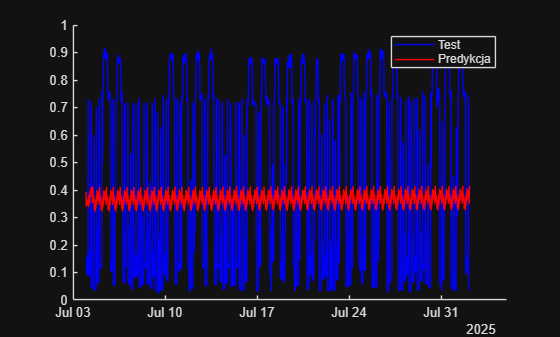

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:test_length), test_data(1:test_length), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:test_length), prediction, 'Color','red','DisplayName','Predykcja');
legend;

y_test = test_data(1:length(prediction))';

mae_score = mae(y_test, prediction)

mae_score = 0.3229

mape_score = mape(y_test, prediction)

mape_score = 87.6543

rmse_score = rmse(y_test, prediction)

rmse_score = 0.3473

r2_classic = R2_classic(y_test, prediction)

r2_classic = -0.0138

r2_alt = R2_alt(y_test, prediction)

r2_alt = 0.0142

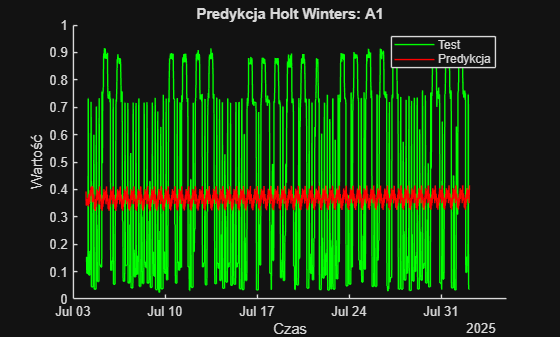


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(prediction)), test_data(1:length(prediction)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(prediction)), prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters: A1")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   prediction(1:dlugosc_testu_oryginalna)', ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, 'pred_ab_A1_SARIMA_month.xlsx');